# **IO207 - Digital Loopback**

The IO207 I/O module provides a total of 128 digital TTL lines, programmable as inputs or outputs in groups of eight channels. Each channel group can be configured to use pull-up resistors (5 V or 3.3 V, ±24 mA), pull-down resistors or floating lines. 

The digital channels are accessible in two main groups (front and rear) of 64 channels on two separate connectors. The driver implements the following additional features for each main group: 

- Option to enable only the first half of the channels of a main group (the rest of the channels are then disabled). This reduces the overall latency of the I/O module, because less data is written to the bus 

- Option to enable synchronous read and write operations on all the channels of a main group. This allows all 64 channels to be simultaneously updated, but also increases the overall latency of the I/O module 

The Read and Write blocks always act on the entire channel group (input or output).

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO207 I/O module installed and one IO207 board extension cable

- 2x connector cable from the I/O module to the terminal board

- 2x 68-pin terminal board with jumper wires

### Test Setup

The first 68 channels are available on the **front** connector of the module itself and the other 68 channels are available on the **rear** board extension cable.

On the terminal board of the TTL digital I/O module, connect the **front** digital output pins of DIO 01 and 17 to the pins of the **front** digital inputs 09 and 25 and connect the **rear** digital output pins of DIO 97 and 113 to the pins of the **rear** digital inputs 105 and 121.  The voltage is left to the default value of 3.3 V.

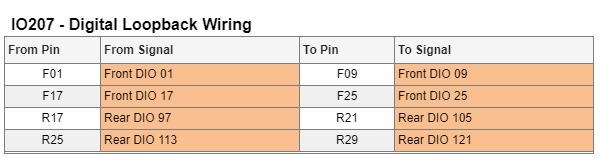

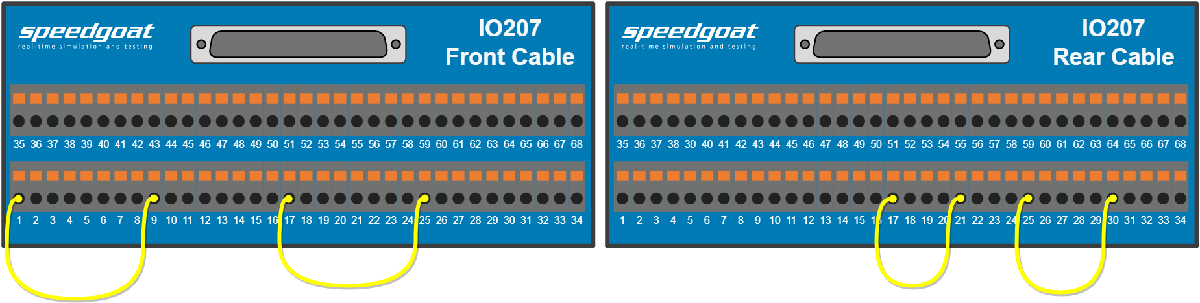

[IO207 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io207_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink Model
modelName = 'sgMdl_IO207_DigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the IO207 Setup,  2x Write and 2x Read blocks.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
stoptime = 2;
pause(stoptime)
tg.stop;

% Number of signals to be viewed in the SDI
numsignals = 5; 
pause(1)

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;
runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", stoptime, "yMin", -0.5, "yMax", 7.5);

### Check the Results

The output is then visible in the Simulink Data Inspector (SDI). You should see 5 square waves, like in the image below:

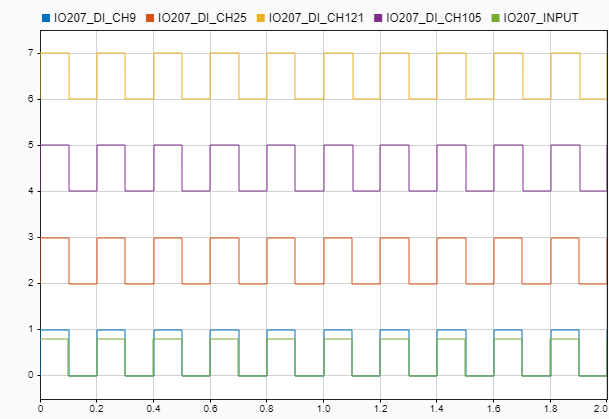

The input signal is represented by the square wave with an amplitude of 0.8. If you zoom on the bottom signals, you will notice that the input signal and the channel 9 signal have a small phase shift. This is due to the simulation step time that creates a shift for each signal that passes through a Simulink block.

## Additional References

- [IO207 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io207)